cd(fileparts(matlab.desktop.editor.getActiveFilename))
close all; clearvars; clc

load("../../results/trmse_raw.mat")

seq_starts = find(y_within.w_trial==1)+1

seq_starts =      2
    11
    20
    29
    38
    47


seq_stops = find(y_within.w_trial==9)+1

seq_stops =     10
    19
    28
    37
    46
    55


delta_between = [];
for i=1:length(seq_starts)
seq = y_between(:,seq_starts(i):seq_stops(i))
delta_seq = seq{:,6:9}-seq{:,1:4}
delta_between = [delta_between, delta_seq];
end

seq = 14×9 table
      y_1        y_2        y_3        y_4        y_5        y_6        y_7        y_8        y_9   
    _______    _______    _______    _______    _______    _______    _______    _______    ________

    0.42876    0.46986    0.46987    0.41732    0.41752    0.45718    0.39423    0.38462     0.34256
    0.35062    0.32878    0.35091    0.33812    0.36282    0.33413    0.35641    0.43904     0.40482
    0.47689    0.29211     0.3156    0.49522    0.74178    0.67027    0.52517    0.39605     0.40236
    0.56538    0.48902    0.48823    0.47889     0.4899     0.4899    0.48989    0.43858     0.17166
    0.69838    0.74453    0.44757    0.35272    0.49026    0.57064    

delta_seq =     0.0284   -0.0756   -0.0852   -0.0748
   -0.0165    0.0276    0.0881    0.0667
    0.1934    0.2331    0.0805   -0.0929
   -0.0755    0.0009   -0.0496   -0.3072
   -0.1277   -0.3093   -0.0589    0.0062
   -0.2707   -0.2666   -0.2670   -0.1719
   -0.0994   -0.0762   -0.0637    0.0851
    0.2098    0.0859   -0.1203    0.0608
   -0.1070   -0.0387   -0.0161   -0.0047
   -0.4083   -0.0361   -0.0007   -0.0322


seq = 14×9 table
     y_10        y_11        y_12       y_13        y_14       y_15       y_16       y_17       y_18  
    _______    ________    ________    _______    ________    _______    _______    _______    _______

    0.14351     0.25239     0.28725    0.32856      0.3154    0.17235    0.23068    0.14713    0.28512
    0.21786    0.048685     0.17341    0.10754     0.13491     0.1382    0.15683    0.23362      0.228
    0.21962     0.16961     0.16795    0.50074     0.52667    0.43254    0.25212    0.24943    0.20027
    0.32873     0.74214     0.70196    0.71516     0.74195    0.74052    0.73971    0.68327    0.21236
    0.53539     0.78357     0.34347    0.12051     0.24185

delta_seq =     0.0288   -0.0217   -0.1401   -0.0434
   -0.0797    0.1081    0.0602    0.1205
    0.2129    0.0825    0.0815   -0.3005
    0.4118   -0.0024   -0.0187   -0.5028
   -0.1643   -0.6327   -0.2211   -0.0130
    0.0423   -0.2487   -0.3562   -0.2427
   -0.0364   -0.0296    0.0120   -0.0116
   -0.0921   -0.0478   -0.0463   -0.0563
   -0.0753   -0.0317   -0.0027   -0.0091
   -0.0370    0.0042    0.0007    0.0056


seq = 14×9 table
     y_19       y_20       y_21       y_22       y_23       y_24       y_25       y_26       y_27  
    _______    _______    _______    _______    _______    _______    _______    _______    _______

    0.44409    0.32224    0.31915    0.24505    0.24611    0.27371    0.27286    0.38006    0.40079
    0.18919    0.23221    0.20193     0.2644    0.24764    0.27069    0.25299    0.27378    0.21304
     0.4515    0.41507    0.43592    0.42221    0.44494    0.41824    0.38785    0.42483    0.30636
    0.34945    0.38794    0.43654    0.38399    0.43902    0.41616    0.42917    0.43206    0.43288
    0.45177    0.47773    0.47499    0.44962    0.45486     0.4899    0.4871

delta_seq =    -0.1704   -0.0494    0.0609    0.1557
    0.0815    0.0208    0.0719   -0.0514
   -0.0333   -0.0272   -0.0111   -0.1158
    0.0667    0.0412   -0.0045    0.0489
    0.0381    0.0094    0.0149    0.0322
    0.0001   -0.0299    0.0797   -0.0095
   -0.1270   -0.0815   -0.0822   -0.0136
   -0.1444    0.0798    0.0333    0.0365
    0.1121    0.0626    0.0094   -0.0026
   -0.0184   -0.0215   -0.0145    0.0047


seq = 14×9 table
     y_28       y_29       y_30        y_31       y_32        y_33        y_34       y_35       y_36  
    _______    _______    _______    ________    _______    ________    ________    _______    _______

    0.10967    0.11192    0.14364     0.11994    0.17894    0.044707    0.056949    0.14005    0.11603
    0.38339    0.28808    0.34174      0.4446    0.27709     0.29186     0.13162    0.20814    0.40162
    0.19964    0.15629    0.30841     0.27312    0.62581     0.61959      0.6085    0.23741    0.65926
    0.21885    0.23879    0.23165     0.22403    0.29589     0.22602     0.21636    0.17424     0.1799
    0.25964    0.32316    0.19717     0.23548     0.2151  

delta_seq =    -0.0650   -0.0550   -0.0036   -0.0039
   -0.0915   -0.1565   -0.1336   -0.0430
    0.4199    0.4522   -0.0710    0.3861
    0.0072   -0.0224   -0.0574   -0.0441
    0.0552    0.2492    0.4259    0.0094
    0.0145    0.0326    0.3589    0.1242
   -0.1627   -0.0469    0.1483    0.0051
   -0.0393    0.1907   -0.3259   -0.2561
    0.0923    0.1241    0.0506    0.3133
    0.0280   -0.0451   -0.0026   -0.0441


seq = 14×9 table
     y_37       y_38       y_39       y_40       y_41       y_42       y_43       y_44       y_45  
    _______    _______    _______    _______    _______    _______    _______    _______    _______

    0.34794    0.28142    0.46651    0.32212    0.23671    0.27021    0.32365    0.25575    0.39048
    0.23057    0.36162    0.23744    0.30423    0.19579    0.25484    0.21657    0.24848    0.22263
    0.37387    0.34654    0.36583    0.28173    0.25187     0.3333     0.3648    0.27742    0.35557
    0.42781    0.38401    0.34445    0.18075    0.42623    0.32379    0.39846    0.26487    0.20385
    0.46926    0.46879    0.44747    0.48547    0.48876    0.31498    0.4069

delta_seq =    -0.0777    0.0422   -0.2108    0.0684
    0.0243   -0.1450    0.0110   -0.0816
   -0.0406    0.0183   -0.0884    0.0738
   -0.1040    0.0145   -0.0796    0.0231
   -0.1543   -0.0618   -0.1434   -0.1581
   -0.0743   -0.1411   -0.0889   -0.1806
   -0.1494   -0.2341    0.0663   -0.0760
   -0.0916   -0.1319   -0.1172    0.0436
   -0.0904    0.0786    0.0163    0.0733
   -0.1794   -0.0557    0.0130   -0.1070


seq = 14×9 table
      y_46        y_47        y_48       y_49       y_50        y_51        y_52        y_53        y_54  
    ________    ________    ________    _______    _______    ________    ________    ________    ________

     0.11581     0.22289     0.19526    0.11674    0.26871    0.064737     0.11155     0.11443      0.1033
     0.33291    0.099544     0.17989    0.13061    0.10199     0.11735     0.10767     0.13496    0.098462
     0.64567     0.27088     0.26178     0.1489    0.23745    0.059847     0.39763     0.15869    0.087884
     0.22281     0.19795     0.20291    0.20167    0.24013    0.045216     0.22902     0.14256    0.091052
     0.69604     0.16365       0.1

delta_seq =    -0.0511   -0.1113   -0.0808   -0.0134
   -0.2156    0.0081   -0.0449   -0.0322
   -0.5858    0.1267   -0.1031   -0.0610
   -0.1776    0.0311   -0.0603   -0.1106
   -0.4976    0.1141    0.1162   -0.1215
   -0.0068   -0.0587   -0.0478   -0.0343
   -0.0973   -0.0551   -0.1185    0.0768
   -0.0133   -0.0333   -0.0358    0.0611
   -0.3389   -0.0962   -0.0644   -0.1104
   -0.1987   -0.0533    0.0087   -0.0043


d_between = [y_between(:,1), array2table(delta_between)]

d_between = 14×25 table
    b_condition    delta_between1    delta_between2    delta_between3    delta_between4    delta_between5    delta_between6    delta_between7    delta_between8    delta_between9    delta_between10    delta_between11    delta_between12    delta_between13    delta_between14    delta_between15    delta_between16    delta_between17    delta_between18    delta_between19    delta_between20    delta_between21    delta_between22    delta_between23    delta_between24
    ___________    ______________    _________

d_within = y_within(any(y_within.w_trial==(1:4),2),["w_task", "w_gesture", "w_trial"])

d_within = 24×3 table
          w_task              w_gesture        w_trial
    __________________    _________________    _______

    "Machine Learning"    "Co-Activation"         1   
    "Machine Learning"    "Co-Activation"         2   
    "Machine Learning"    "Co-Activation"         3   
    "Machine Learning"    "Co-Activation"         4   
    "Machine Learning"    "Differentiation"       1   
    "Machine Learning"    "Differentiation"       2   
    "Machine Learning"    "Differentiation"       3   
    "Machine Learning"    "Differentiation"       4   
    "Human Learning"      "Co-Activation"         1   
    "Human Learning"      "Co-Activation"         2   
    "Human Learning"      "Co-Activation"         3   
    "Human Learning"      "Co-Activation"         4   
    "Human Learning"      "Differentiation"       1   
    "Human Learning"      "Differentiation"       

### Step 1. Visualize Raw Data in Panels

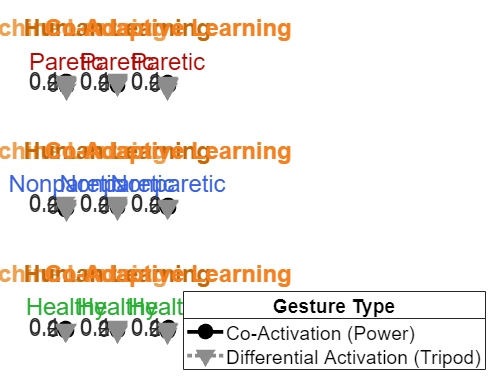

tlo = tiledlayout('flow');
fontsize(tlo, 20, "points")
% tlo.Units = 'inches';
% tlo.OuterPosition = [0 0 17 10.5];
ax_handle_list = [];
for cond = ["par", "xpar", "hlt"]
    y_cond = d_between(d_between.b_condition==cond,2:end);
    for task = ["Machine Learning", "Human Learning", "Co-Adaptive Learning"]
        y_coact = y_cond(:, and(d_within.w_task == task, d_within.w_gesture == "Co-Activation"));
        y_diffact = y_cond(:, and(d_within.w_task == task, d_within.w_gesture == "Differentiation"));
        ax_handle = nexttile;
        ax_handle_list = [ax_handle_list, ax_handle];
        hold on
        plot(y_coact{:,:}', '-ok', 'MarkerFaceColor','k', 'LineWidth',3,'MarkerSize',10 )
        plot(y_diffact{:,:}', ':v', 'MarkerFaceColor',"#8c8c8c", 'LineWidth',3,'MarkerSize',10, 'Color',"#8c8c8c")
        hold off
        title(task)
        switch task
            case "Machine Learning"
                title(task, 'Color', "#f0a150")
            case "Human Learning"
                title(task, 'Color', "#c76706")
            case "Co-Adaptive Learning"
                title(task, 'Color', "#f48020")
        end
        switch cond
            case "par"
                subtitle("Paretic", 'Color', "#b30600")
            case "xpar"
                subtitle("Nonparetic", 'Color', "#3760e3")
            case "hlt"
                subtitle("Healthy", 'Color', "#29af34")
        end
        xticks(1:9)
        yticks(0:0.2:0.8)
    end
end
legend_handle = legend(["Co-Activation (Power)","", "", "", "Differential Activation (Tripod)"], "Location","eastoutside");
title(legend_handle, "Gesture Type")
linkaxes(ax_handle_list, 'xy')
ylim(1.1*[min(delta_between,[], 'all'), max(delta_between,[], 'all')])
xlim([0 5])
% title(tlo, sprintf("%s Vs. Trial Count", upper(metric_type)))
set(ax_handle_list, 'FontSize', 18)

### Export to R

r_dataframe = [];
for i=1:height(d_between)
    if or(d_between{i,1} == "par", d_between{i,1} == "xpar")
        p_id = i+mod(i,2);
    else
        p_id = i;
    end
    p_tbl = array2table([d_between{i,2:end}', repmat(sprintf("p%02d",p_id), height(d_within),1), repmat(d_between{i,1}, height(d_within),1), d_within{:,:}], ...
        "VariableNames", ["rmse", "p_id", "p_cond", "task_type", "gesture_type", "trial_num"]);
    r_dataframe = [r_dataframe; p_tbl];
end

r_dataframe = convertvars(r_dataframe, ["rmse"], 'double');
r_dataframe = convertvars(r_dataframe, ["trial_num"], 'double');
r_dataframe = convertvars(r_dataframe, ["gesture_type", "task_type", "p_cond", "p_id"], 'categorical');
r_dataframe = r_dataframe(:,{'rmse' 'trial_num' 'gesture_type' 'task_type' 'p_cond', 'p_id'})

r_dataframe = 336×6 table
       rmse       trial_num     gesture_type         task_type        p_cond    p_id
    __________    _________    _______________    ________________    ______    ____

      0.028416        1        Co-Activation      Machine Learning     par      p02 
     -0.075632        2        Co-Activation      Machine Learning     par      p02 
     -0.085248        3        Co-Activation      Machine Learning     par      p02 
     -0.074761        4        Co-Activation      Machine Learning     par      p02 
      0.028847        1        Differentiation    Machine Learning     par      p02 
     -0.021716        2        Differentiation    Machine Learning     par      p02 
      -0.14012        3        Differentiation    Machine Learning     par      p02 
    

writetable(r_dataframe, '../../temp-data/rdf_rmse_delta_9.csv','WriteMode','overwrite')

### 2-Way ANOVA

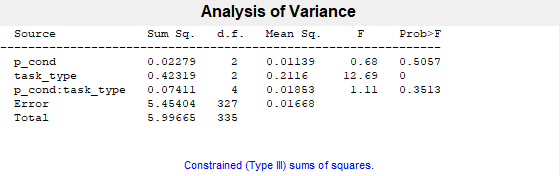

pvals =     0.5057
    0.0000
    0.3513


anova_tbl = 6×7 cell array
    {'Source'          }    {'Sum Sq.'}    {'d.f.'}    {'Singular?'}    {'Mean Sq.'}    {'F'       }    {'Prob>F'    }
    {'p_cond'          }    {[ 0.0228]}    {[   2]}    {[        0]}    {[  0.0114]}    {[  0.6832]}    {[    0.5057]}
    {'task_type'       }    {[ 0.4232]}    {[   2]}    {[        0]}    {[  0.2116]}    {[ 12.6863]}    {[4.9398e-06]}
    {'p_cond:task_type'}    {[ 0.0741]}    {[   4]}    {[        0]}    {[  0.0185]}    {[  1.1108]}    {[    0.3513]}
    {'Error'           }    {[ 5.4540]}    {[ 327]}    {[        0]}    {[  0.0167]}    {0×0 double}    {0×0 double  }
    {'Total'           }    {[ 5.9967]}    {[ 335]}    {[        0]}    {0×0 double}    {0×0 double}    {0×0 double  }


stats = struct with fields:
         source: 'anovan'
          resid: [336×1 double]
         coeffs: [16×1 double]
            Rtr: [9×9 double]
       rowbasis: [9×16 double]
            dfe: 327
            mse: 0.0167
    nullproject: [16×9 double]
          terms: [3×2 double]
        nlevels: [2×1 double]
     continuous: [0 0]
         vmeans: [2×1 double]
       termcols: [4×1 double]
     coeffnames: {16×1 cell}
           vars: [16×2 double]
       varnames: {2×1 cell}
       grpnames: {2×1 cell}
        vnested: []
            ems: [4×4 double]
          denom: []
        dfdenom: []
        msdenom: []
         varest: []
          varci: []
       txtdenom: []
         txtems: []
        rtnames: []


terms =      1     0
     0     1
     1     1


[pvals,anova_tbl,stats, terms] = anovan(r_dataframe{:,"rmse"}, ...
    {r_dataframe{:,"p_cond"}, r_dataframe{:,"task_type"}}, ...
    'varnames',["p_cond", "task_type"], ...
    'model',2)

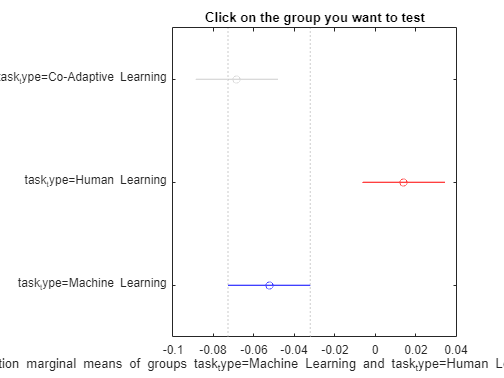

ans =     1.0000    2.0000   -0.1231   -0.0824   -0.0417    0.0000
    1.0000    3.0000   -0.0566   -0.0159    0.0248    0.6303
    2.0000    3.0000    0.0258    0.0665    0.1072    0.0004


figure
multcompare(stats, "Dimension",[2])